# Simulate the process u_t in section 2.4

% Example of Kalman filter
% Simulate N samples of a process to test your code.

A = [1 0.8 0.8];

ee = randn(1,600);

y = filter(1, A, ee);

y= y(101:end);

%y = load("Code\data\tar2.dat"); % Simulated data

N = length(y);

% Define the state space equations.
A = [1 0
     0 1];
C = [1 0];
Re = [0 0 ; 0 0]; % State covariance matrix
Rw = 1.25; % Observation variance

% Set some initial values
Rxt1 = 10 * eye(2); % R{1|0}^{x,x}
het = zeros(1,N); % Estimated prediction error.
xt = zeros(2,N); % Estimated states.
yhat1 = zeros(N + 1,1); % Estimated 1-step prediction.
yhat2 = zeros(N + 2,1); % Estimated 2-step prediction.

% Where should the loop start and stop?
for t = 3 : N

    % Update the predicted state
    xt1 = A * xt(:,t-1); % x{t|t-1}
    Ct = [-y(t-1), -y(t-2)]; % C{t|t-1}

    % Update the parameter estimates.
    Ry = Ct * Rxt1 * Ct' + Rw; % R{t|t-1}^{y,y}
    Kt = Rxt1 * Ct'/Ry; % Kt
    yhat = Ct * xt1; % yhat{t|t-1}
    het(t) = y(t) - yhat; % Prediction error
    xt(:,t) = xt1 + Kt * het(t); % x{t|t}

    % Update the covariance matrix estimates.
    Rxt =  Rxt1 - Kt * Ry * Kt'; % R^{x,x}_{t|t}
    Rxt1 = A * Rxt * A' + Re; % R^{x,x}_{t+1|t}

    % Form yhat{t+1|t}.
    Ct1 = [-y(t), -y(t-1)]; % C{t+1|t}
    yhat1(t+1) = Ct1 * xt(:,t); % yhat{t+1|t}

    % Form yhat{t+2|t}.
    Ct2 = [-yhat1(t+1), -y(t)]; % C{t+2|t}
    yhat2(t+2) = Ct2 * xt(:,t); % yhat{t+2|t}

end


## Plot predictions

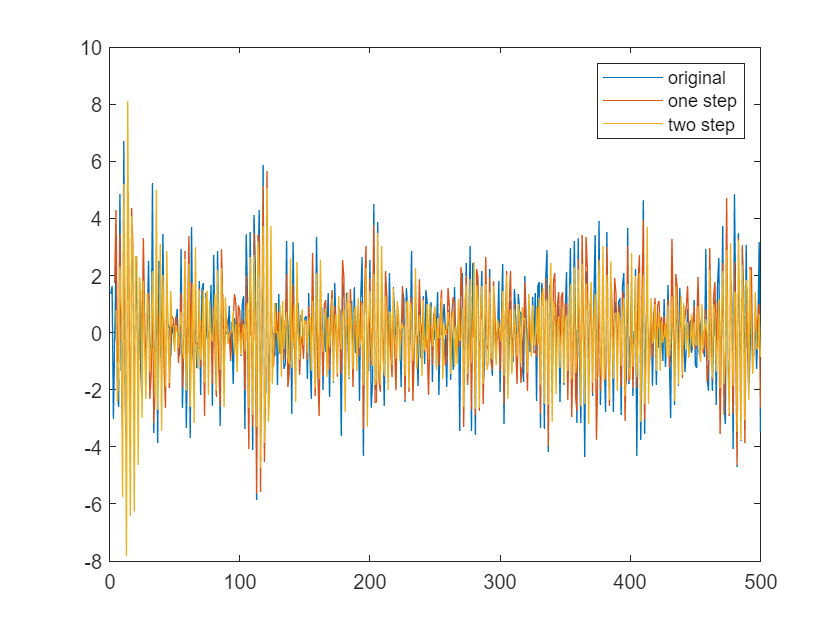

figure;
plot(y)
hold on
plot(4:N, yhat1(4:N))
hold on
plot(5:N, yhat2(5:N))
legend("original", "one step", "two step")
hold off

## Plot the paramaters for the AR(2) process

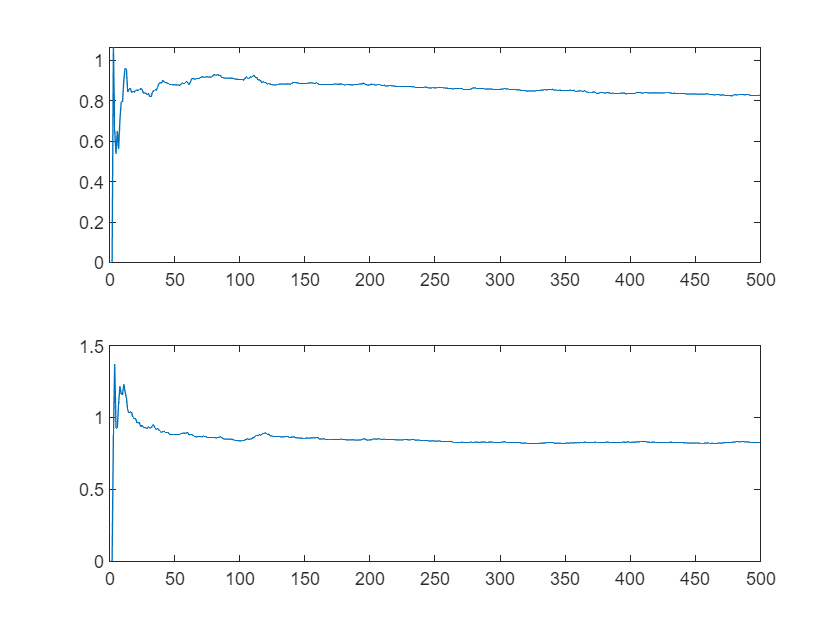

figure;
subplot(211)
plot(xt(1,:))
subplot(212)
plot(xt(2,:))

## Markov process

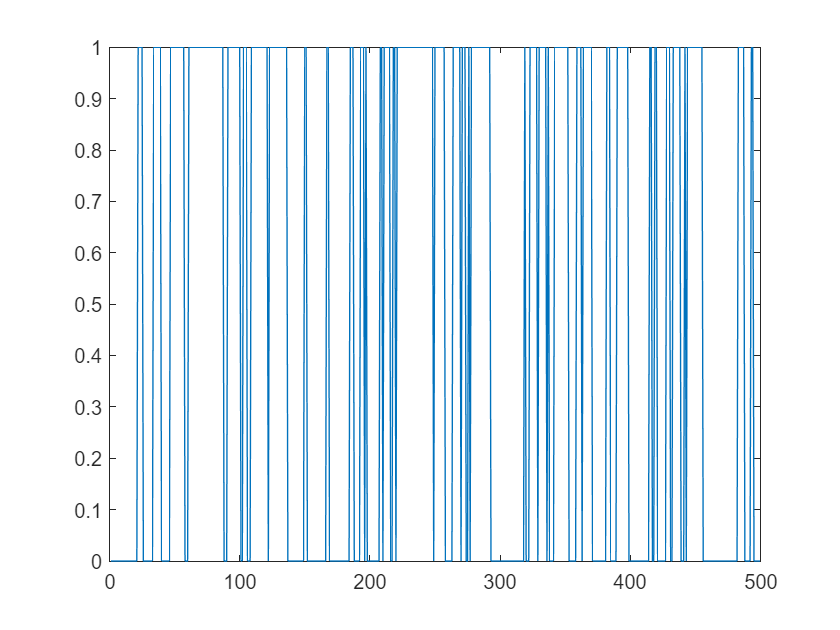

M = [7/8 1/8; 1/8 7/8];
i = 0;
N = 500;
pswitch = 1/8;
ut = zeros(1,500);
for t = 2:500
    if rand < pswitch
        ut(t) = 1 - ut(t-1);
    else
        ut(t) = ut(t-1);
    end
end

plot(ut)

sum(ut<1)

ans = 250

## 2.1 Recursive least squares estimation

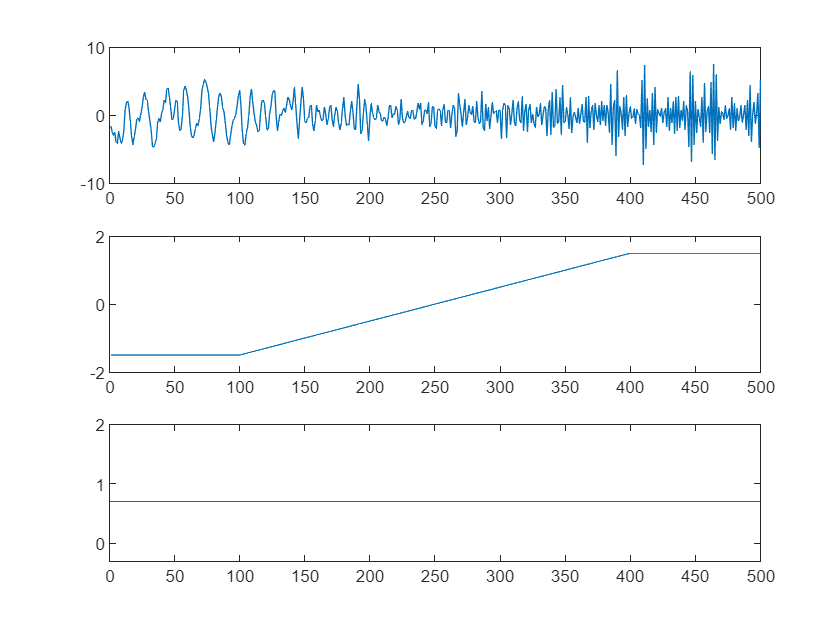


y = load("Code\data\tar2.dat");
param = load("Code\data\thx.dat");

figure;
subplot(311);
plot(y)
subplot(312)
plot(param(:,1))
subplot(313)
plot(param(:,2))

## Recursive Least Square

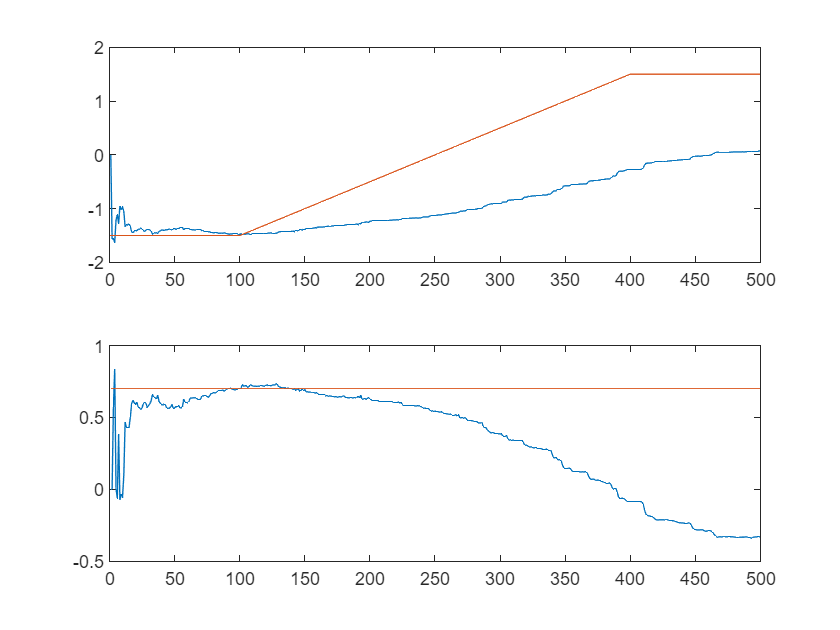

Aest = zeros(length(y), 3);

yhat = zeros(1,length(y));

X = recursiveAR(2);
X.ForgettingFactor = 1;
X.InitialA = [1 0 0];

for kk = 1:length(y)
    [Aest(kk,:), yhat(kk)] = step(X, y(kk));
end

figure;
subplot(211)
plot(Aest(:,2))
hold on
plot(param(:,1))
subplot(212)
plot(Aest(:,3))
hold on
plot(param(:,2))

## Forgetting factor .95

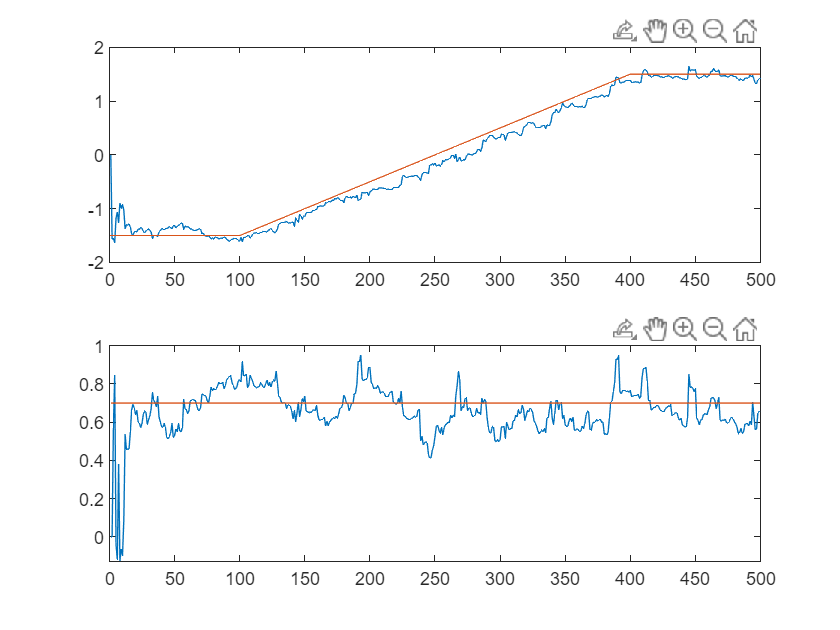


Aest = zeros(length(y), 3);

yhat = zeros(1,length(y));

X = recursiveAR(2);
X.ForgettingFactor = .95;
X.InitialA = [1 0 0];

for kk = 1:length(y)
    [Aest(kk,:), yhat(kk)] = step(X, y(kk));
end

figure;
subplot(211)
plot(Aest(:,2))
hold on
plot(param(:,1))
subplot(212)
plot(Aest(:,3))
hold on
plot(param(:,2))

## Forgetting factor .9

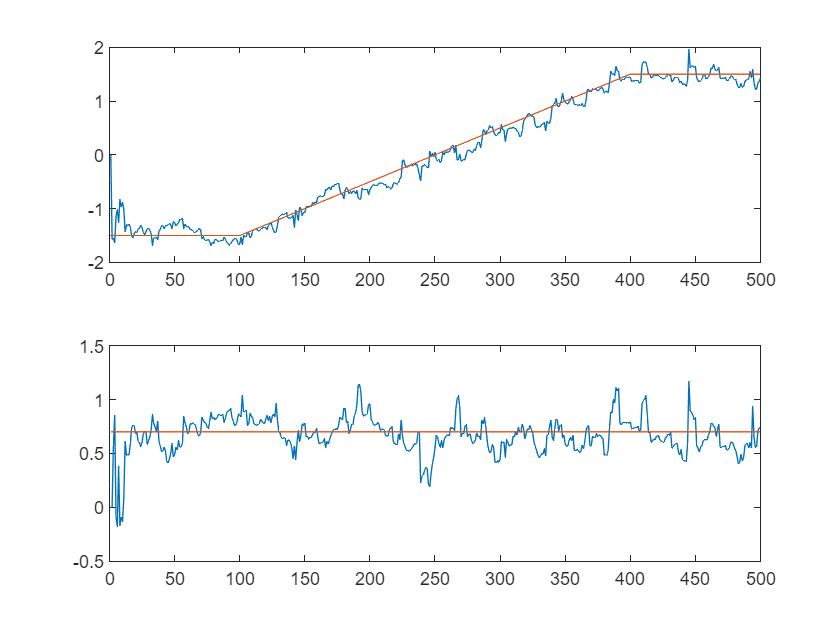


Aest = zeros(length(y), 3);

yhat = zeros(1,length(y));

X = recursiveAR(2);
X.ForgettingFactor = .9;
X.InitialA = [1 0 0];

for kk = 1:length(y)
    [Aest(kk,:), yhat(kk)] = step(X, y(kk));
end

figure;
subplot(211)
plot(Aest(:,2))
hold on
plot(param(:,1))
subplot(212)
plot(Aest(:,3))
hold on
plot(param(:,2))

## LSE of Lambda

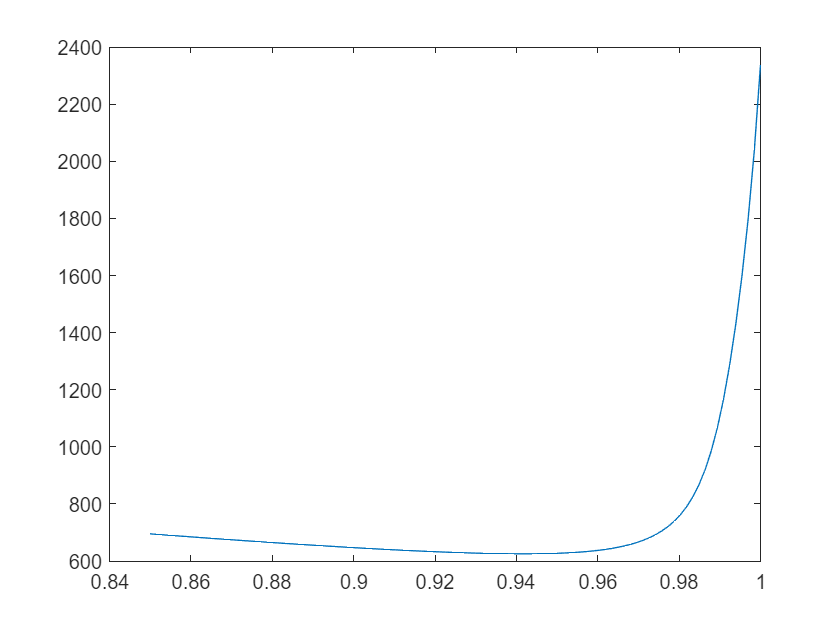

n = 100;
lambdaline = linspace(0.85, 1, n);
ls2 = zeros(n, 1);
yhat = zeros(n, 1);

for i = 1:length(lambdaline)
    reset(X);
    X.ForgettingFactor = lambdaline(i);
    X.InitialA = [1 0 0];

    for kk = 1:length(y)
        [~, yhat(kk)] = step(X, y(kk));
    end

    ls2(i) = sum((y - yhat).^2);
end
figure;
plot(lambdaline, ls2)

min(ls2)

ans = 625.1102

## 2.2 Kalman filtering of time series


y = load("Code\data\tar2.dat"); % Simulated data

N = length(y);

% Define the state space equations.
A = [1 0
     0 1];
C = [1 0];
Re = [.004 0 ; 0 0]; % State covariance matrix
Rw = 1.25; % Observation variance

% Set some initial values
Rxt1 = 10 * eye(2); % R{1|0}^{x,x}
het = zeros(1,N); % Estimated prediction error.
xt = zeros(2,N); % Estimated states.
yhat1 = zeros(N + 1,1); % Estimated 1-step prediction.
yhat2 = zeros(N + 2,1); % Estimated 2-step prediction.

% Where should the loop start and stop?
for t = 3 : N

    % Update the predicted state
    xt1 = A * xt(:,t-1); % x{t|t-1}
    Ct = [-y(t-1), -y(t-2)]; % C{t|t-1}

    % Update the parameter estimates.
    Ry = Ct * Rxt1 * Ct' + Rw; % R{t|t-1}^{y,y}
    Kt = Rxt1 * Ct'/Ry; % Kt
    yhat = Ct * xt1; % yhat{t|t-1}
    het(t) = y(t) - yhat; % Prediction error
    xt(:,t) = xt1 + Kt * het(t); % x{t|t}

    % Update the covariance matrix estimates.
    Rxt =  Rxt1 - Kt * Ry * Kt'; % R^{x,x}_{t|t}
    Rxt1 = A * Rxt * A' + Re; % R^{x,x}_{t+1|t}

    % Form yhat{t+1|t}.
    Ct1 = [-y(t), -y(t-1)]; % C{t+1|t}
    yhat1(t+1) = Ct1 * xt(:,t); % yhat{t+1|t}

    % Form yhat{t+2|t}.
    Ct2 = [-yhat1(t+1), -y(t)]; % C{t+2|t}
    yhat2(t+2) = Ct2 * xt(:,t); % yhat{t+2|t}

end


## Plot the paramaters

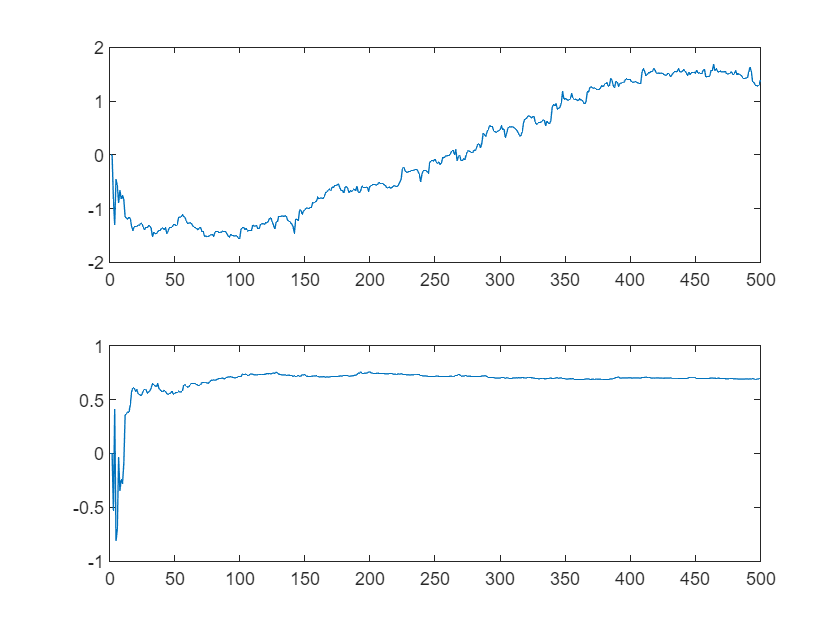

figure;
subplot(211)
plot(xt(1,:))
subplot(212)
plot(xt(2,:))

xt(2,end) %% a2 value

ans = 0.6928

## Error of one step estimate

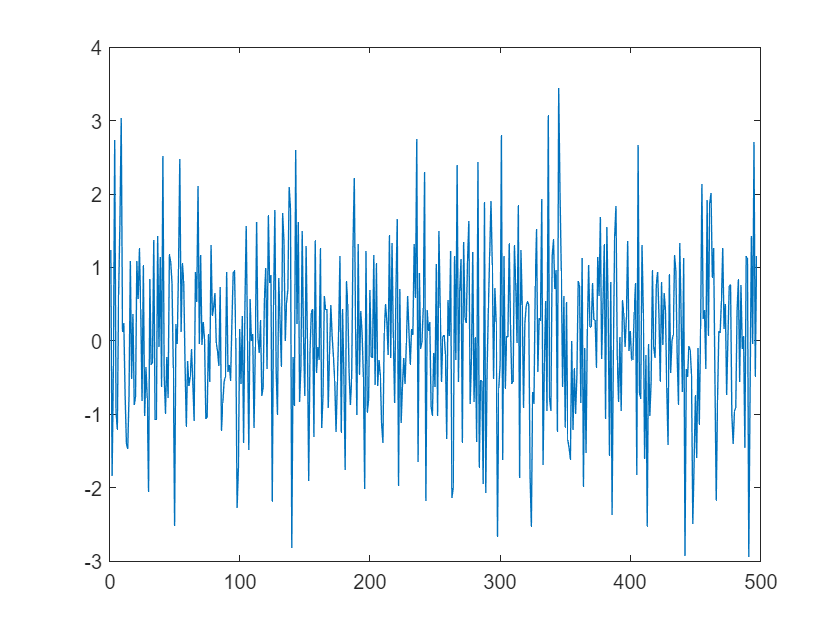

figure;
plot(y(4:end) - yhat1(4:end-1))

sum((y(4:end) - yhat1(4:end-1)).^2)

ans = 598.0365

%% FEE